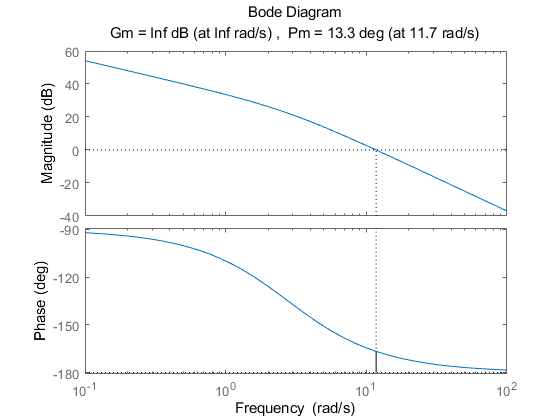

clear;
s=tf('s');
k_p=2550; tau_p=0.36; k_c=0.02;
P=k_p/s/(tau_p*s+1);
C1=k_c;

margin(C1*P)

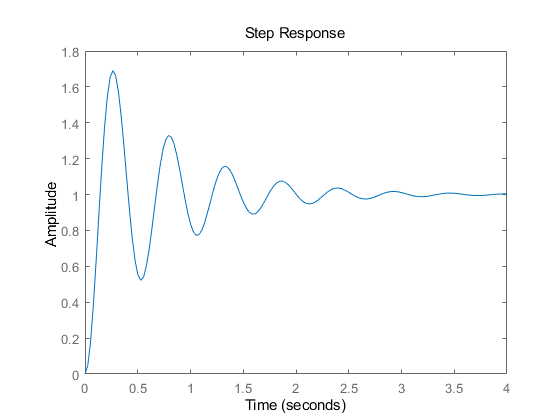

step(C1*P/(1+C1*P))     %y(r)

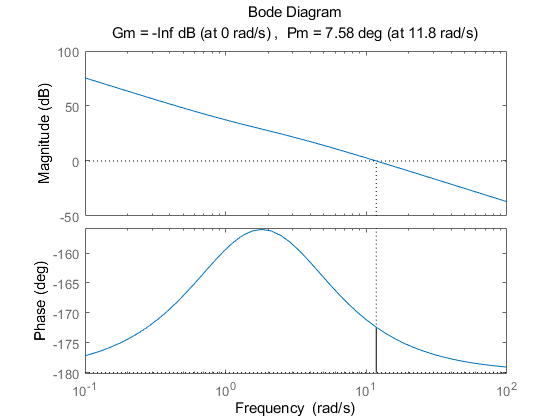


C2=k_c*(10*s+11.74)/10/s;
margin(C2*P)

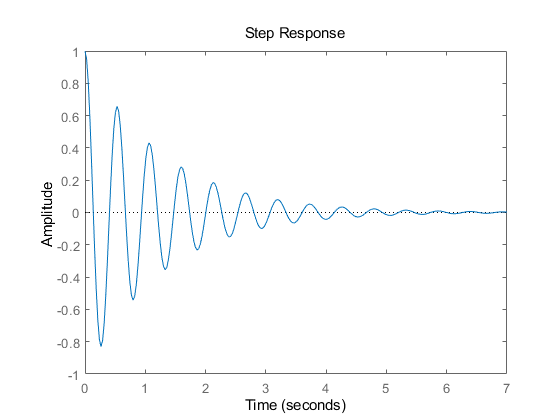

step(1/(1+C2*P))        %e(r)

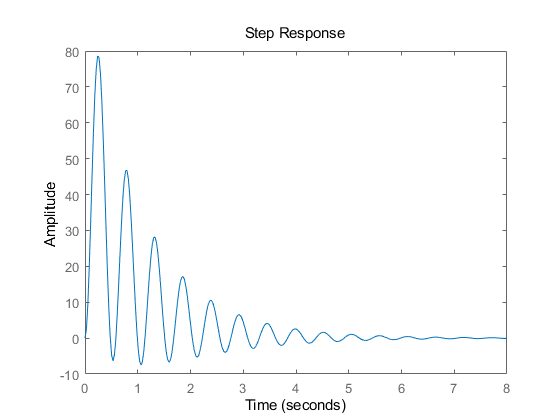

step(P/(1+C2*P))        %y(d)

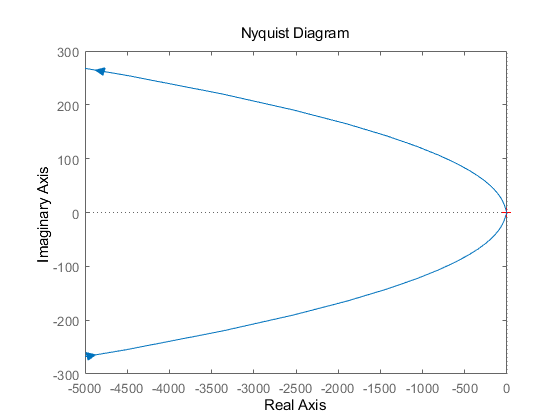


nyquist(C2*P)

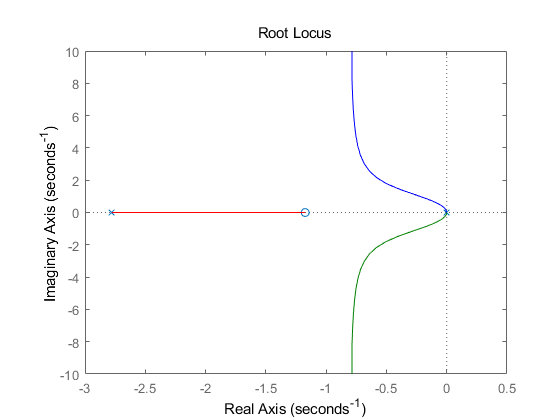

rlocus(C2*P/k_c)

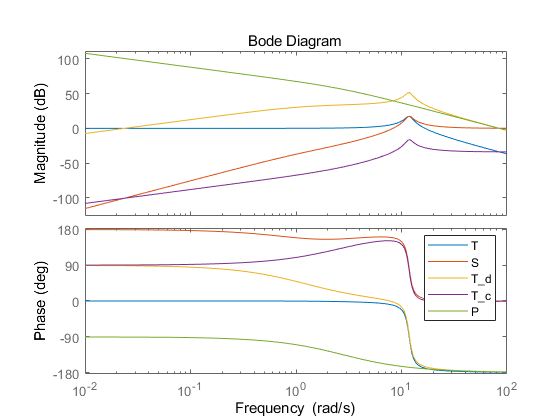

figure()
hold on
bode(C2*P/(1+C2*P))
bode(1/(1+C2*P))
bode(P/(1+C2*P))
bode(C2/(1+C2*P))
bode(P)
legend('T','S','T_d','T_c','P')
hold off

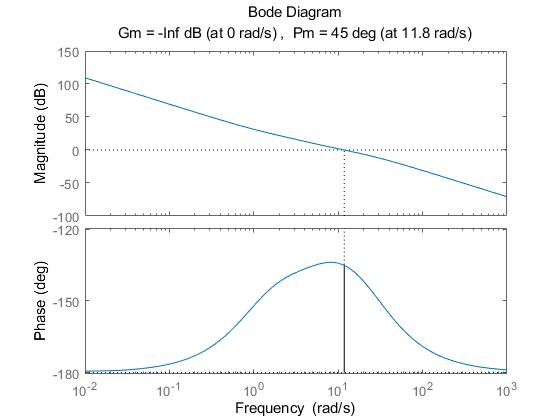


phi=(45-7.58)/180*pi;
syms a
aa=solve((a-1)/(a+1)==sin(phi),a);
a=double(sqrt(aa));

C3=C2*(a*s+11.74)/(s+a*11.74);

margin(C3*P)

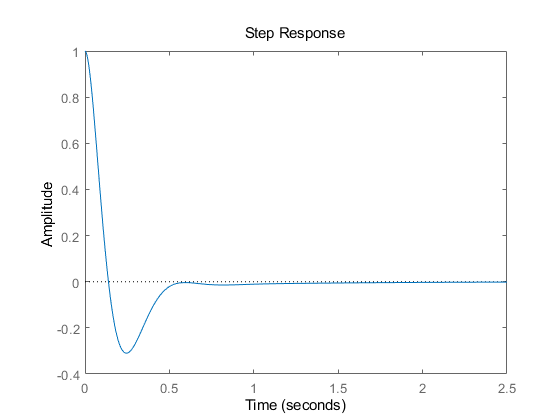

step(1/(1+C3*P))

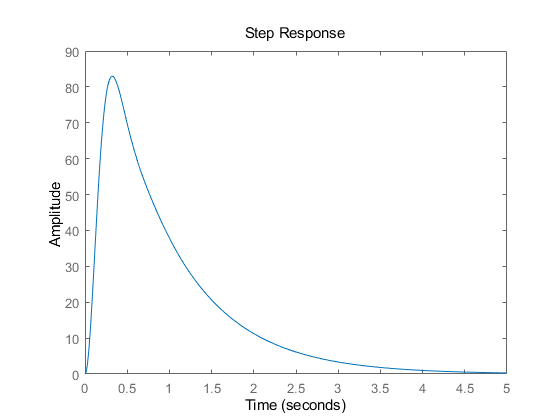

step(P/(1+C3*P))

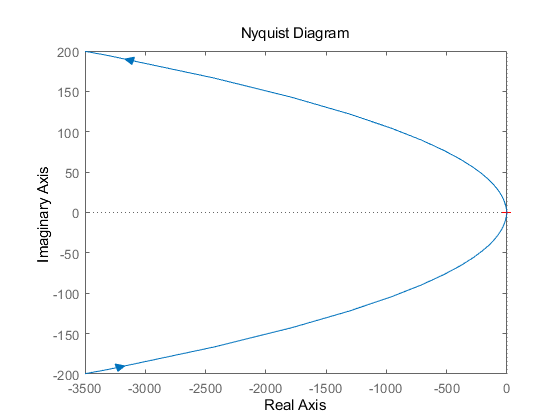


nyquist(C3*P)

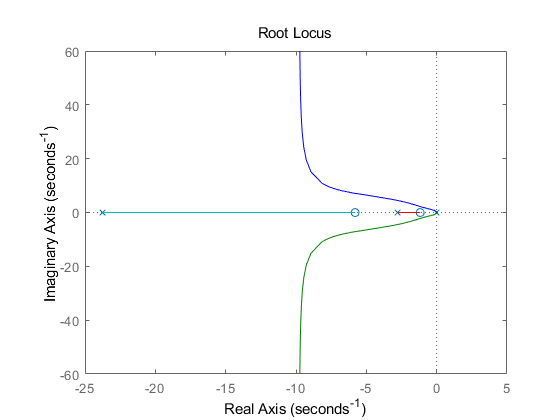

rlocus(C3*P/k_c)

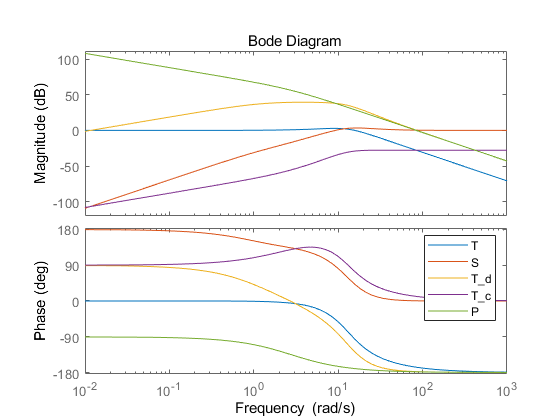

figure()
hold on
bode(C3*P/(1+C3*P))
bode(1/(1+C3*P))
bode(P/(1+C3*P))
bode(C3/(1+C3*P))
bode(P)
legend('T','S','T_d','T_c','P')
hold off